%М-Actuators Lab 5 2024
clc; clear all;

## Simulation data

R20XX           =   matlabRelease.Release % "R2020a"  "R2020b" "R2021a" "R2021b" "R2022a" "R2022b"  matlabRelease.Release;

R20XX = "R2022a"

Lab_No          =   5;
CourseName      =   "Actuators";
ModelName       =   CourseName + "_Lab_" + string (Lab_No) +"_" + R20XX + ".slx"

ModelName = "Actuators_Lab_5_R2022a.slx"

## Drive parameters (from Actuators - Bachelor - Automation - Lab 5.xlsx file)

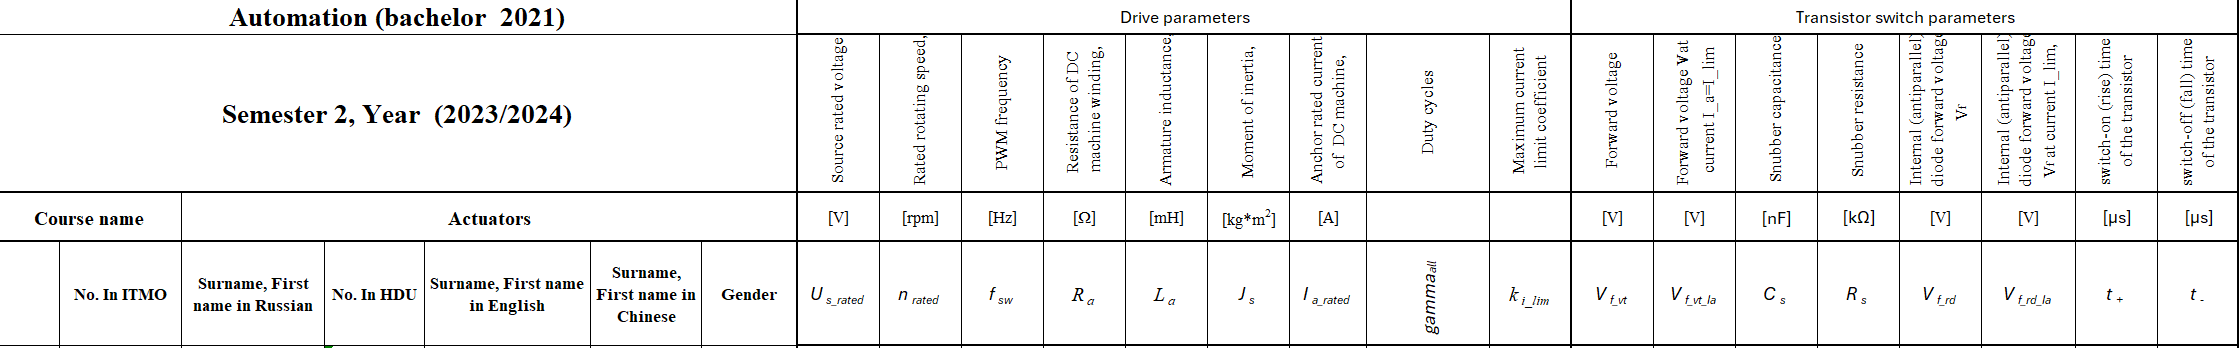

U_s_rated       =   75;%220;                                     % - Rated source voltage, V;
n_rated         =   600;%750;                                     % - Rated rotating speed, rpm;                      
f_sw            =   3500;%5000;                                    % - PWM frequency, Hz;
R_a             =   0.075;%27.20;                                   % - ResistanCe of DC machine winding (armature), Ω;
L_a             =   0.554e-3; %0.128;                                   % - Anchor inductance, H, %tau_e=La/Ra;
J_s             =   0.238;%0.004;                                   % - Moment of inertia, kg*m^2;
I_a_rated       =   50; %170/220;                                 % - Anchor rated current of DC machine, A;
k_i_lim         =   1.8;%2;                                       % - Current limitation coefficient;
gamma_all       =   [1.00;...                                 % - duty cycles gamma_all;
                     0.75;...
                     0.5;...
                     0.1]; %

## Evaluations

Equations to describe electric drive


$$\tau_{a} \frac {\mathrm d T_{e} }{\mathrm d t } = \beta (\omega_{0}-\omega_{m}) - T_{e} \\

J_S \frac {\mathrm d \omega_{1} }{\mathrm d t } = T_e- T_L.$$


or:


$$\frac {\mathrm d T_{e} }{\mathrm d t } =-(\frac {1} {\tau_a})T_e- \frac {\beta}{\tau_a}\omega_{m} + \frac {\beta}{\tau_a}\omega_{0} \\

\frac {\mathrm d \omega_{m} }{\mathrm d t } = \frac {1} {\beta \tau_m}T_e- \frac {1} {\beta \tau_m}T_L.$$


P               =   U_s_rated*I_a_rated                       % - Power of DC link of power source (W)

P = 3750

I_a_sc          =   U_s_rated/R_a                             % - Short circuit current, A;

I_a_sc = 1000

w_m_rated       =   (2*pi*n_rated)/60                         % - Rated rotating speed, rad/s;

w_m_rated = 62.8319

k_e             =   (U_s_rated-R_a*I_a_rated )/w_m_rated      % - EMF constant, V*s/rad

k_e = 1.1340

k_m             =   k_e                                       % - Electromechanical constant, N*m/A;

k_m = 1.1340

T_e_rated       =   I_a_rated*k_m                             % - Rated Torque of the DC machine, N*m;

T_e_rated = 56.6989

T_e_max         =   k_i_lim*T_e_rated                         % - Maximum torque, N*m;

T_e_max = 102.0581

T_e_st          =   k_m*I_a_sc                                % - Starting torque, N*m;

T_e_st = 1.1340e+03

K_eff_rated     =   T_e_rated*w_m_rated/(P)*100               % - Rated efficiency, %

K_eff_rated = 95

tau_e           =   L_a/R_a                                   % - Electromagnetic time constant, s;

tau_e = 0.0074

w0              =   U_s_rated/k_e                             % - Idle speed, rad/s;

w0 = 66.1388

tau_m           =   (J_s*w0)/T_e_st                           % - Electromechanical time constant, s; 

tau_m = 0.0139

I_lim           =   k_i_lim*I_a_rated                         % - Current limit value, A; 

I_lim = 90

## Transistor parameters

### Transistor switched on circuit parameters 

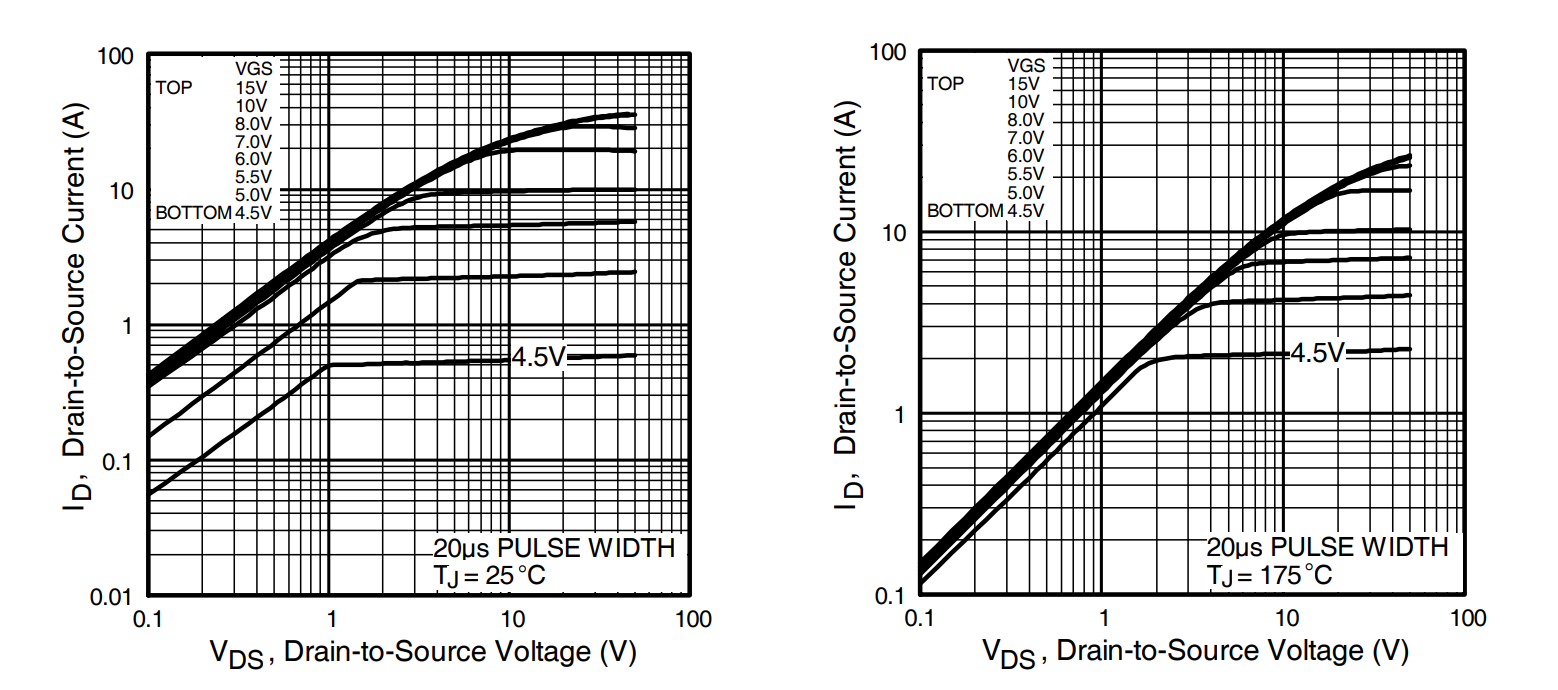

Vf_vt           =   0;                                          % - Forward voltage Vf (V) (For MOSFET may be considered equal to 0) 
Vf_vt_Ia        =   1.2;%1.3;                                        % - Forward voltage Vf at rated current I_lim (V)
R_on_vt         =   (Vf_vt_Ia-Vf_vt)/I_lim;                     % - MOSFET / IGBT resistance R_on (Ω)

### Snubber circuit parameters 

Cs_vt           =   330e-9;                                     % - Snubber resistance Rs (Ω)
Rs_vt           =   1e6;                                        % - Snubber capacitance Cs (F)

### 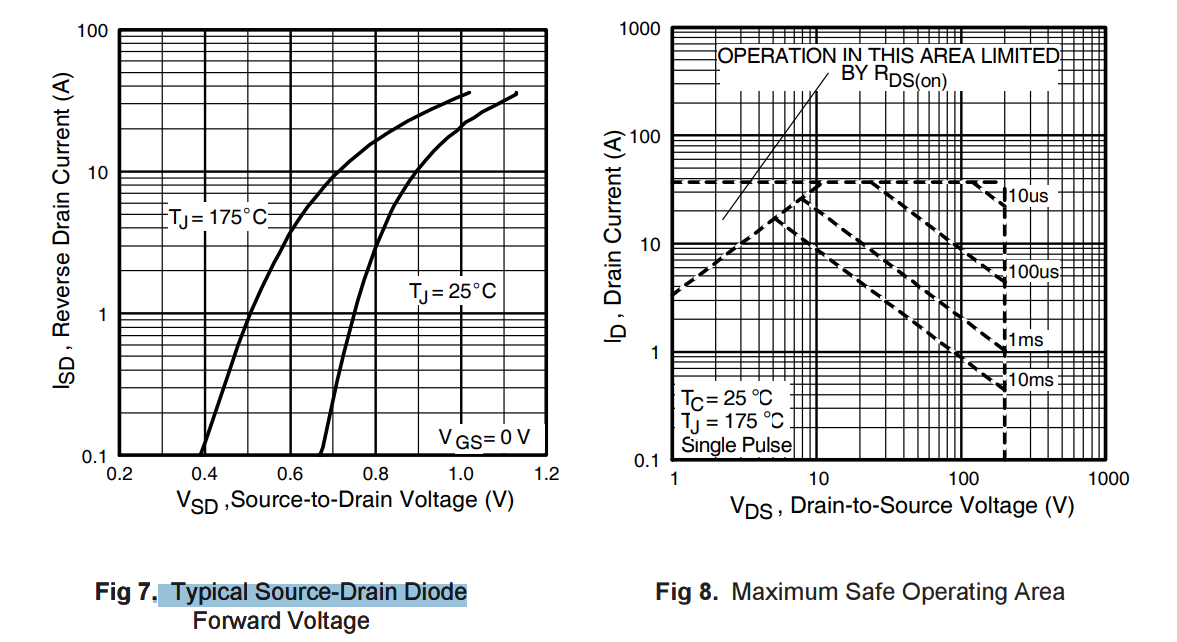

### Reverse (antiparallel) diode parameters

Vf_rd           =   0.85;%0.65;                                       % - Internal (antiparallel) diode forward voltage Vf(V)
Vf_rd_Ia        =   0.95;%0.75;                                       % - Internal (antiparallel) diode forward voltage at rated current I_lim (V)
R_on_rd         =   (Vf_rd_Ia-Vf_rd)/I_lim;                     % - Internal (antiparallel) diode resistance Rd(Ω)

### Transistor rise/fall time8

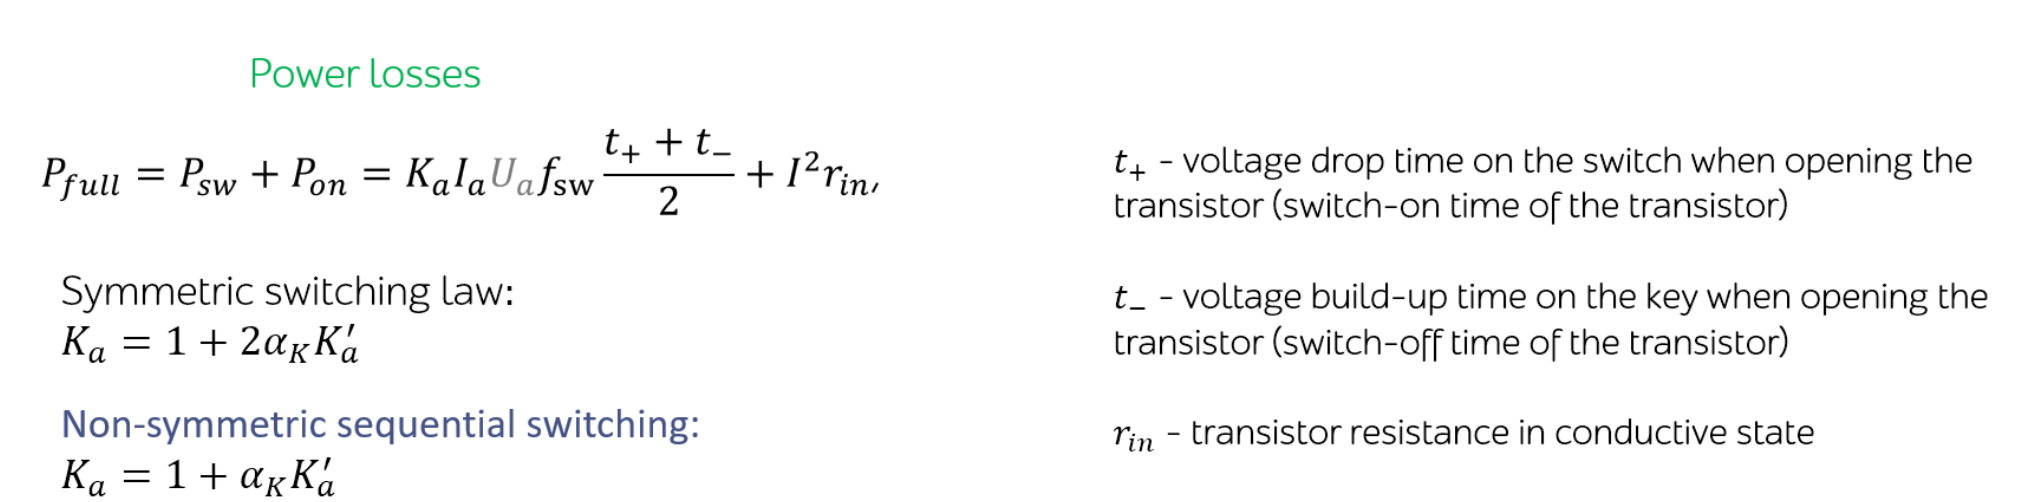

t_rize          =   2e-7;    %                                 %-    switch-on (rise) time of the transistor
t_fall          =   4e-7;    %                                %-    switch-off (fall) time of the transistor
tplus           =   t_rize;
tminus          =   t_fall;

## Drive with converter

This section provides drive parameters correction on the iffluence of power switch parameters

R_a_total       =   R_a+2*R_on_vt;                              % - Full active resistance of armature cirquit (Ω)
tau_e           =   L_a/R_a_total;                              % - Electromagnetic time constant, s; 
U_s             =   U_s_rated + I_a_rated*2*R_on_vt + 2*Vf_vt;  % - + I_lim*R_a
f_sw_opt_s_sw   =   0;
f_sw_opt_n_sw   =   0;

## Load

T_Load          =   k_i_lim* T_e_rated;                           % - Load torque set up as constant load;

## Converter model parameters

T_sw            =   1/f_sw;                                     % - Switching period / conwerter time constant, s;
beta            =   T_e_st/w0;                                  % - Speed-Torque characteristic stiffness \beta;
C_dc_filter     =   350e-6;                                     % - DC link filter capacitor, F;

## Power losses and efficiency

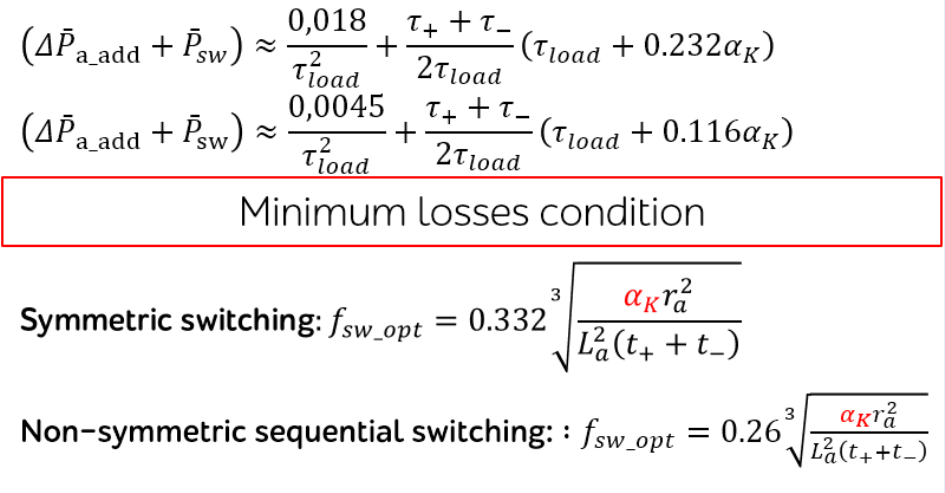

alfa_k          =   I_lim/I_a_rated                             % ok

alfa_k = 1.8000

tau_load        =   L_a/R_a_total*f_sw;

## Symmetric switching

  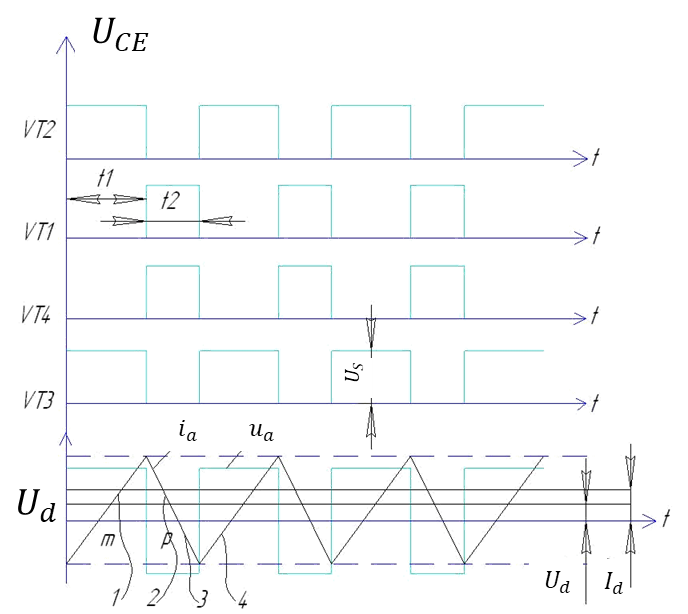

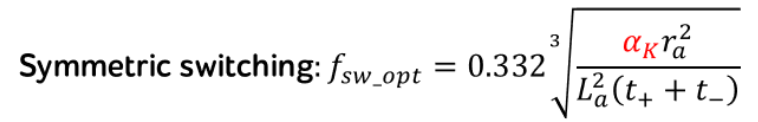

P_dop           =   0.018/tau_load^2+(tplus+tminus)/2*tau_load*(tau_load+0.232*alfa_k);
f_sw_opt_s_sw   =   0.332*(nthroot((alfa_k*R_a_total^2/L_a^2/(tplus+tminus)), 3));
% ***
T_sw_opt_s_sw   =   1/f_sw_opt_s_sw;
T_sw_opt_s_sw   =   round(T_sw_opt_s_sw,6);
f_sw_opt_s_sw   =   1/T_sw_opt_s_sw;

## Asymetric sequential switching

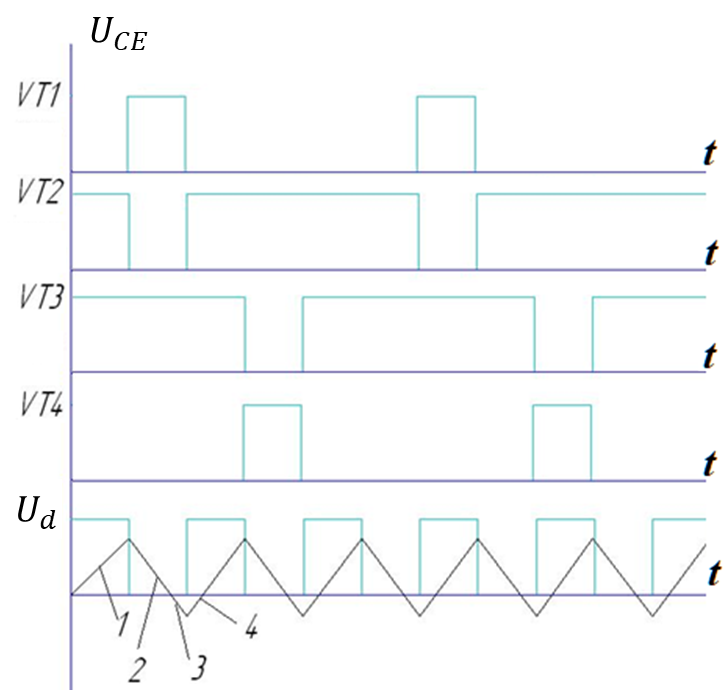

P_dop           =   0.0045/tau_load^2+(tplus+tminus)/2*tau_load*(tau_load+0.116*alfa_k);
f_sw_opt_n_sw   =   0.26*(nthroot((alfa_k*R_a_total^2/L_a^2/(tplus+tminus)), 3));
% ***
T_sw_opt_n_sw   =   1/f_sw_opt_n_sw;
T_sw_opt_n_sw   =   round(T_sw_opt_n_sw,6);
f_sw_opt_n_sw   =   1/T_sw_opt_n_sw;

## Mechanical characteristic                   

**Set up required duty cycles values (Gamma) for  mechanical characteristics**

n                =    size(gamma_all ,1)

n = 4

Stop_time        =  50*tau_m

Stop_time = 0.6941

***Do not forget to change switching frequency ***$f_{\textrm{sw}}$** to **${f_{\textrm{sw}} }_{{\textrm{opt}}_{s_{\textrm{sw}} } }$** or **${f_{\textrm{sw}} }_{{\textrm{opt}}_{n_{\textrm{sw}} } }$***when changing switching method from Symetric to any other or vice versa any Non-symmetric (asymmetric) to symmetric    ***

**Do not forget to set appropriate swiching frequency**

%f_sw             =   f_sw_opt_s_sw;                   % f_sw for symmetric switching
%f_sw             =   f_sw_opt_n_sw;                   % f_sw for asymmetric sequential  and diagonal switching
T_sw               =    1/f_sw;                          % Reassigned switching period, s;

**Uncomment "Ctrl+R" lines 73 - 121 for mechanical characteristics**

**Pay attention how manual switches should be set in model.**

**Do not forget to attention how manual switches should be set in model.**

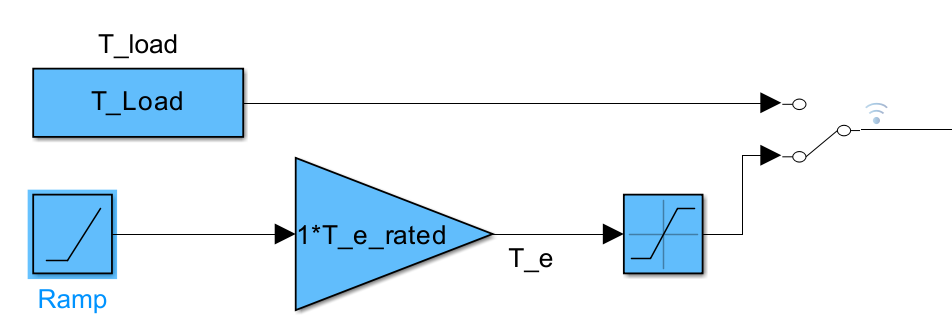

% figure
% syms T_e
% for i               =   1   :   1   :  n
%     gamma           =   gamma_all(i)                              % - set up duty cycle
%     T_e_st          =   k_m*gamma*U_s/R_a_total;
%     sim (ModelName)                                               % - this file should be in the same folder with Actuators_Lab№_R20XXx.mlx
%     T_e_st          =   k_m*gamma*U_s_rated/R_a;
%     w_0             =   (gamma)*(U_s_rated)/k_e;           
%     w_ref           =   w_0-(T_e*(R_a))/(k_e*k_m);
%     w_0_conv        =   (gamma)*(U_s-2*Vf_vt)/k_e;
%     w_ref_conv      =   w_0_conv-(T_e*(R_a_total))/(k_e*k_m);
%     T_Load_var      =   0   :   0.1 :   k_m*gamma*U_s_rated/R_a;
%     w_idle          =   double(subs(w_ref,      T_e, T_Load_var));
%     w_idle_conv     =   double(subs(w_ref_conv, T_e, T_Load_var));
%     plot(T_Load_var/T_e_rated, w_idle/w_m_rated,'Color','g','LineWidth',2)
%     hold on;
%     plot(T_Load_var/T_e_rated,w_idle_conv/w_m_rated,'Color','b','LineWidth',2)
%     hold on;
%     plot(Current_speed.signals(3).values*k_m/T_e_rated, Current_speed.signals(2).values/w_m_rated  ,'Color','r','LineWidth',0.5);
%     hold on;
%     T_e_st          =   k_m*U_s_rated/R_a;
% end
% grid on;
% if f_sw==f_sw_opt_s_sw
%     SW_type='Symmetric';
% elseif f_sw==f_sw_opt_n_sw
%     SW_type='Asymmetric';
% else
%     SW_type='Not set'
% end
% xlim([0 T_e_st/T_e_rated])
% ylim([0 1.15])
% xlabel('T_e / T_e_ _r_a_t_e_d')
% ylabel('\omega / \omega_m_ _r_a_t_e_d')
% legend('DC Drive theoretical characteristic','DC Drive with power converter','DC Drive with PWM simulation', 'Location','northoutside')
% v=axis;
% text(T_e_st/T_e_rated, 0.7,   {  strcat('U_s_ _r_a_t_e_d=',         num2str(U_s_rated,      '%3.2f'), ' [V] ' );...
%                                  strcat('U_s=',                     num2str(U_s,            '%3.2f'), ' [V] ' );...
%                                  strcat('f_s_w=',                   num2str(f_sw,           '%3.2f'), ' [Hz]' );...
%                                  strcat('Switching type: ',         SW_type                                   );...
%                                  strcat('f_s_w_ _o_p_t_ _s_ _s_w=', num2str(f_sw_opt_s_sw,  '%3.2f'), ' [Hz]' );...
%                                  strcat('f_s_w_ _o_p_t_ _n_ _s_w=', num2str(f_sw_opt_n_sw,  '%3.2f'), ' [Hz]' );...
%                                  strcat('I_a_ _r_a_t_e_d=',         num2str(I_a_rated,      '%3.1f'), ' [A] ' );...
%                                  strcat('T_e_ _r_a_t_e_d=',         num2str(T_e_rated,      '%3.1f'), ' [N*m]');...
%                                  strcat('k_l_i_m=',                 num2str(k_i_lim,          '%3.1f'), '     ' )},...
%       'BackgroundColor', [1 1 1])
% 
% 
% hold off;

## Efficiency characteristic

## Comment "Ctrl+R" lines 73** - 121 ** for Efficiency characteristic

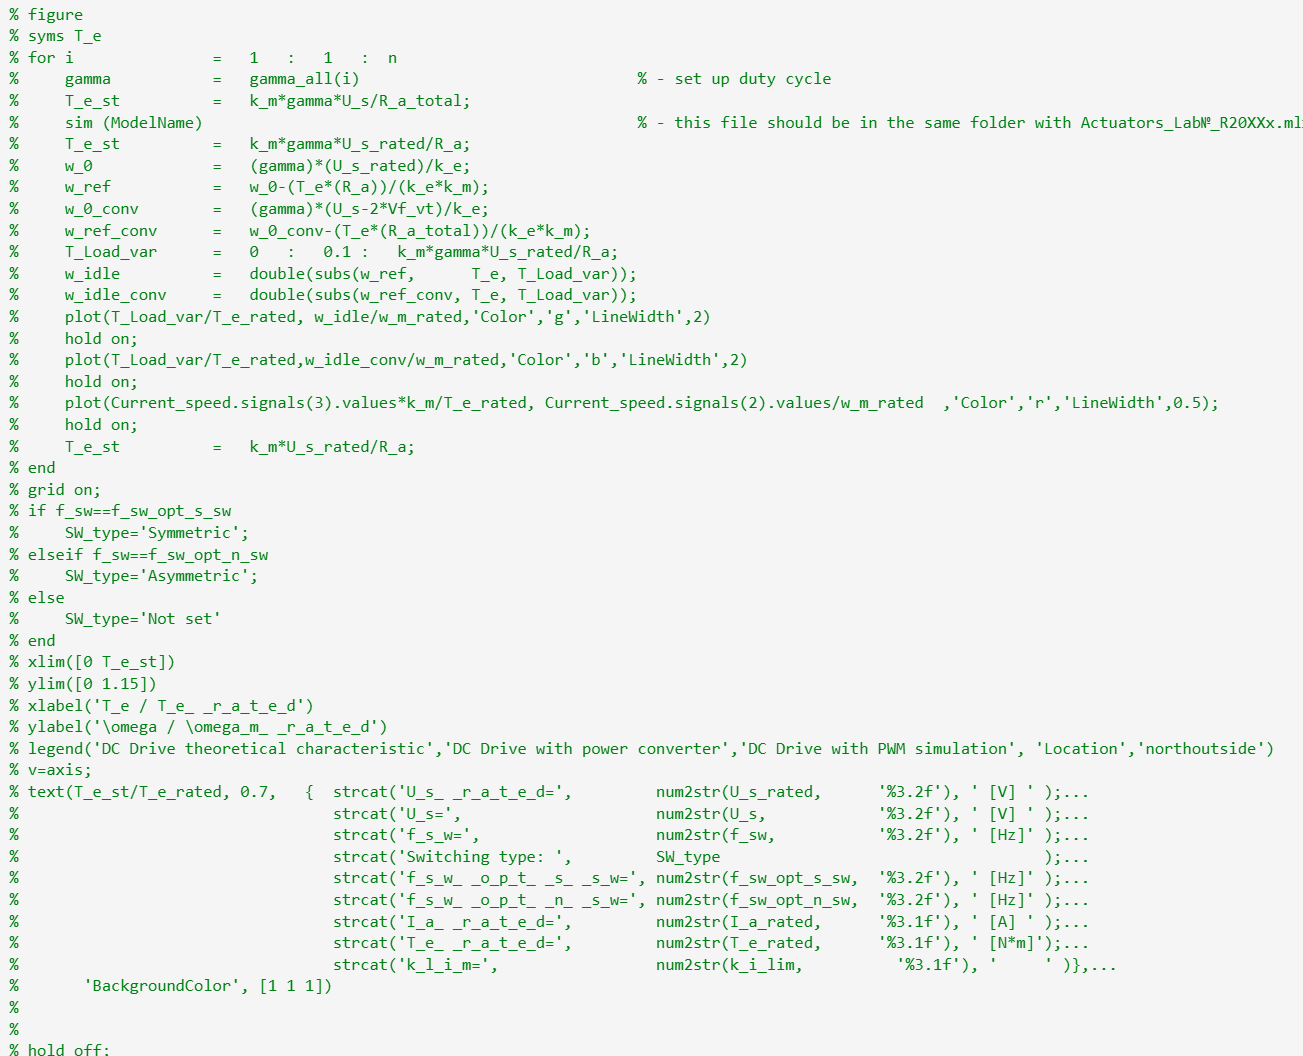

**Set up gamma = 0.5 and **$T_{\textrm{load}} =T_{e_{\textrm{rated}} }$** and comment "Ctrl+R" lines 73 - 121 for energy efficiency experiment**

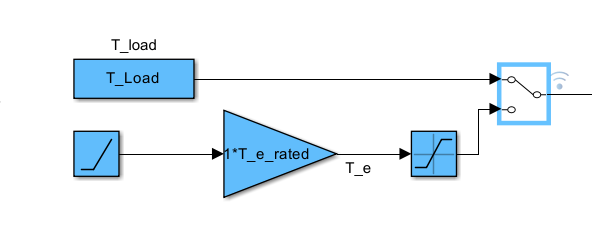

**You may uncomment frequency required and evaluate this selection only with F9**

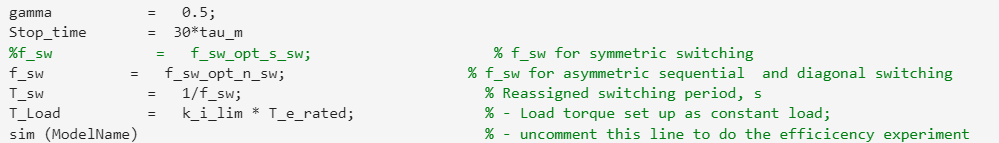

or

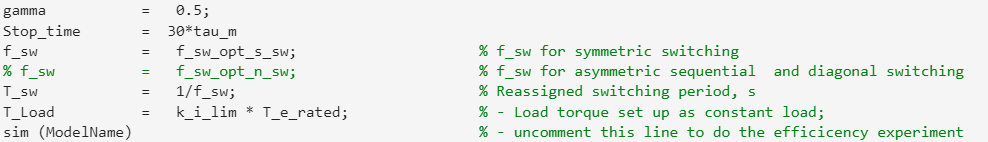

gamma           =   0.75;
Stop_time       =   30*tau_m

Stop_time = 0.4164

f_sw           =   f_sw_opt_s_sw;                     % f_sw for symmetric switching
%f_sw          =   f_sw_opt_n_sw;                     % f_sw for asymmetric sequential  and diagonal switching
T_sw            =   1/f_sw;                            % Reassigned switching period, s
T_Load          =   k_i_lim * T_e_rated;               % - Load torque set up as constant load;
sim (ModelName)                                        % - uncomment this line to do the efficicency experiment